## Matlab Error anaylsis

Error Anaylsis of follwing equation


$$\frac{1}{x}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


where b is the section within the ln

where 

load ErrorAnalysis.mat R
load ErrorAnalysis.mat T
load ErrorAnalysis.mat alpha
load ErrorAnalysis.mat energy_ev
load ErrorAnalysis.mat voltages_1
load ErrorAnalysis.mat voltages_0
load ErrorAnalysis.mat std_0

alpha_squared = alpha.^2;

x = R;
y = T;
z = 0.44*10^(-3); %0.000417


$$\frac{d}{dx}=\frac{x^2y^2\left(\frac{ \frac{8xy^2-4(1-x)^3}{2 \sqrt{4x^2y^2+(1-x)^4} }+2(1-x) }{2x^2y^2} -  \frac{ \sqrt{4x^2y^2+(1-x)^4}-(1-x)^2 }{x^3y^2}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$
 

which in plain text is

dx = (2.*x.^2.*y.^2.*(((8.*x.*y.^2-4.*(1-x).^3)./(2.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) +2.*(1-x))./(2.*x.^2.*y.^2) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^3.*y.^2)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)

dx =    78.9754
  156.1718
  211.6300
  250.9645
  216.8795
  175.4750
  131.0792
  110.9981
  101.7116
   97.6752



$$\frac{d}{dy} = \frac{2x^2y^2\left(\frac{2}{y\sqrt{4x^2y^2+(1-x)^4}} - \frac{\sqrt{4x^2y^2+(1-x)^4}-(1-x)^2}{x^2y^3}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$


dy = (2.*x.^2.*y.^2.*(((2)./(y.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^2.*y.^3)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2))

dy =    31.9256
   33.4816
   34.5420
   35.3704
   35.2986
   35.1066
   34.8291
   34.8829
   35.1166
   35.4667



$$\frac{d}{dz} = \frac{1}{z^2}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


dz = ((1)./(z.^2)).*log((sqrt((1-R).^4+4.*T.^2.*R.^2)-(1-R).^2)./(2.*T.^2.*R.^2))

dz = 	1.0e+06 *

   -2.7417
   -5.7326
   -7.0703
   -7.8035
   -7.1057
   -6.1089
   -4.7547
   -3.9713
   -3.5419
   -3.3183


Errors of respective variables

% error on voltage
errVoltage = std_0

errVoltage = 	1.0e+-6 *

    0.4366
    0.4108
    0.4441
    0.4173
    0.4003
    0.4120
    0.4085
    0.3185
    0.4814
    0.4872



% error on Transmission Coefficient
errT = T.*(((errVoltage./voltages_0).^2+(errVoltage./voltages_1).^2).^0.5);

% other errors
errz = 0.01*10^(-3);
errx = 0.05*R;
erry = errT;

err_alpha = sqrt((dx.*errx).^(2)+(dy.*erry).^(2)+(dz.*errz).^(2));

alpha_GaAs = alpha

alpha_GaAs = 	1.0e+03 *

    0.0148
    0.0018
         0
    0.0007
    0.0054
    0.0113
    0.0195
    0.0261
    0.0313
    0.0357


eV_energy = energy_ev

eV_energy =     3.3930
    3.3839
    3.3747
    3.3657
    3.3567
    3.3477
    3.3388
    3.3299
    3.3211
    3.3123



err_p = 100*(err_alpha./alpha_GaAs)

err_p = 	1.0e+05 *

    0.0121
    0.2543
       Inf
    2.5338
    0.1372
    0.0383
    0.0132
    0.0057
    0.0057
    0.0047



n=10

n = 10

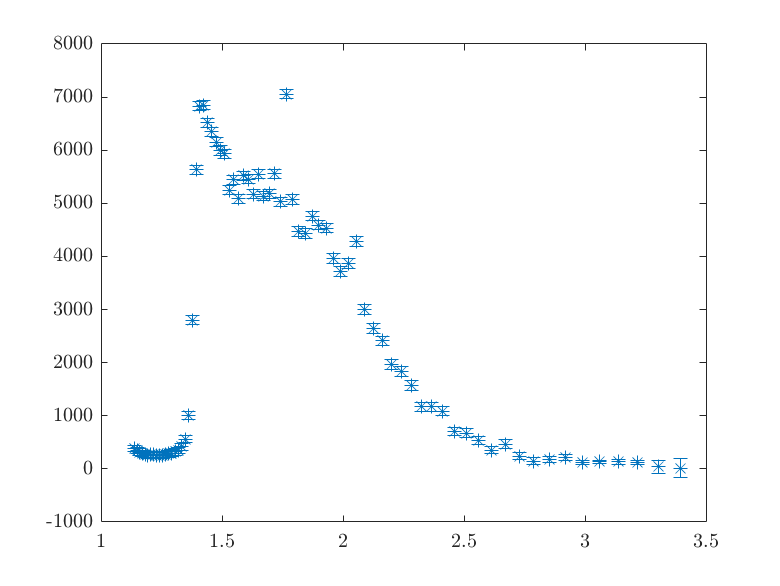


figure(1)
errorbar(energy_ev(1:n:end),alpha(1:n:end),err_alpha(1:n:end), '*')

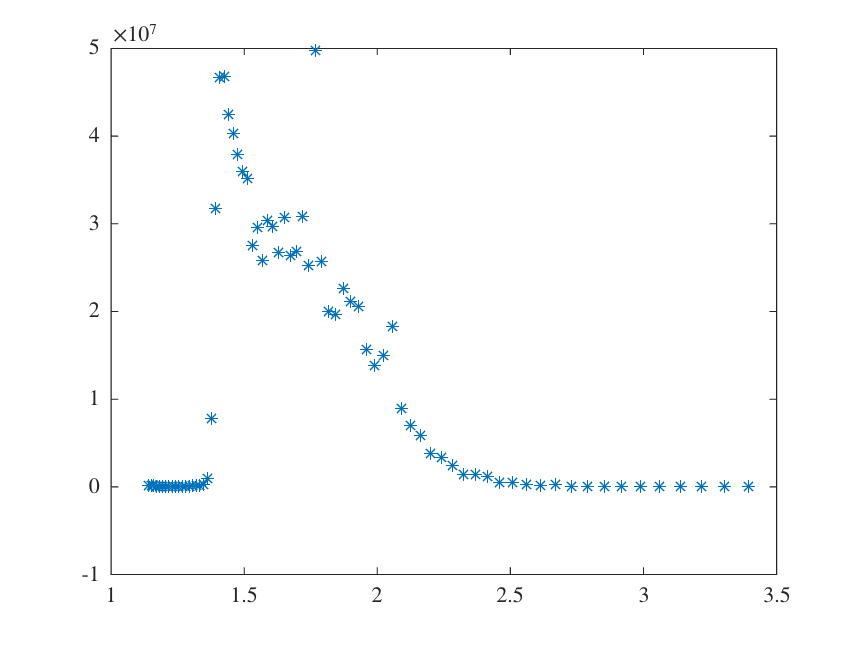


figure(2)
errorbar(energy_ev(1:n:end), alpha_squared(1:n:end), err_alpha(1:n:end)*2, '*')

MyCoeffs = coeffvalues(fitresult);

Unrecognized function or variable 'fitresult'.


var_err = confint(fitresult);

bandgap = (-MyCoeffs(2))/(MyCoeffs(1));

c_err = abs(var_err(1,2)-var_err(2,2))/2;
m_err = abs(var_err(1,1)-var_err(2,1))/2;

err = sqrt(((MyCoeffs(2)/MyCoeffs(1)^2)^2)*m_err^2 + ((1/MyCoeffs(1))^2)*c_err^2);

new_err = bandgap*sqrt((c_err/MyCoeffs(2))^2 + (m_err/MyCoeffs(1))^2);